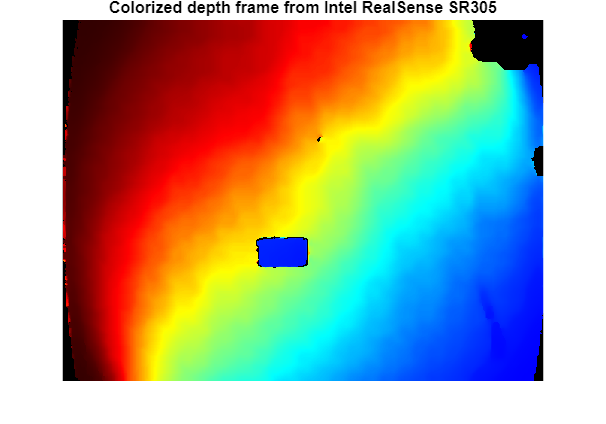

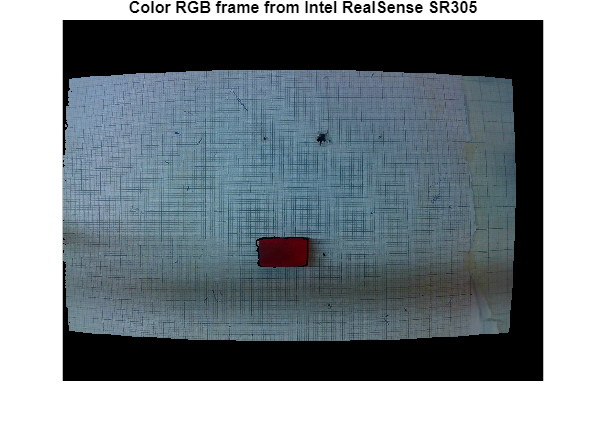

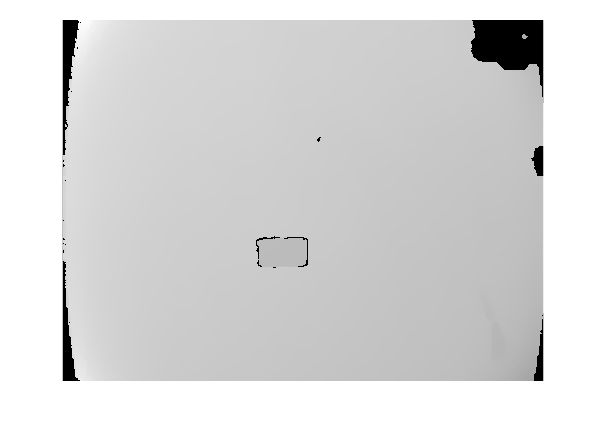

clc; clear; close all;

[imgDepth, imgRGB] = depth_example();


[rows, cols, ~] = size(imgRGB)

rows = 480

cols = 640


% Resize depth image
imgDepth = imresize(imgDepth, [rows, cols], 'nearest');
depthData = double(imgDepth);

% Synchronize dimensions
[dRows, dCols] = size(depthData);
rows = min(rows, dRows);
cols = min(cols, dCols);
imgRGB = imgRGB(1:rows, 1:cols, :);
depthData = depthData(1:rows, 1:cols);


% 2. Segment Red Block
imgLab = rgb2lab(imgRGB);
[L, a, b] = imsplit(imgLab);

% Thresholding for red (Adjust thresholds if needed)
redMask = a > 20 & b > 10; 
redMask = imclose(redMask, strel('disk', 5)); % Bridge gaps
redMask = bwareaopen(redMask, 500);           % Remove noise


% Getting corners+center of the block
stats = regionprops(redMask, 'ConvexHull', 'Orientation');
hull = stats.ConvexHull;

% Use the 'Orientation' and 'Centroid' directly from stats
theta = stats.Orientation; % in degrees
cent = regionprops(redMask, 'Centroid');
block_cx = cent.Centroid(1);
block_cy = cent.Centroid(2);

% For the visual outline, it's safer to use 'BoundingBox' 
% or compute the 4 corners using the angle:
L = stats.MajorAxisLength / 2;
W = stats.MinorAxisLength / 2;
alpha = deg2rad(-theta); % Orientation is counter-clockwise

% Relative corners of a centered rectangle
cx = [-L, L, L, -L, -L];
cy = [-W, -W, W, W, -W];

% Rotate corners
rect_x = block_cx + cx*cos(alpha) - cy*sin(alpha);
rect_y = block_cy + cx*sin(alpha) + cy*cos(alpha);

% center of the block
block_cx = mean(rect_x(1:4));
block_cy = mean(rect_y(1:4));


% Depth of the block from the camera (z value)
row_idx = max(1, min(round(block_cy), rows));
col_idx = max(1, min(round(block_cx), cols));

height = imgDepth(redMask > 0); 
Z = median(height(height > 0)) * 100; 


% X and Y values for the Transformation Matrix
fx = 475.2710; fy = 475.2711; % Focal lengths
cx_img = cols / 2; cy_img = rows / 2; % center of the image

X = (block_cx - cx_img) * Z / fx;
Y = (block_cy - cy_img) * Z / fy;


% Computing the Rotation Matrix
theta = deg2rad(stats.Orientation);

% 3x3 Rotation about Z-axis
R_cb = [ cos(theta),  sin(theta), 0;
        -sin(theta),  cos(theta), 0;
         0,           0,          1];

% Computing the Transformation Matrix
T_cb = [R_cb, [X; Y; Z]; 
        0, 0, 0, 1];

% Display output
fprintf('--- 4x4 Transformation Matrix (Camera to Block) ---\n');

--- 4x4 Transformation Matrix (Camera to Block) ---


disp(T_cb);

    0.9928   -0.1202         0   -1.8960
    0.1202    0.9928         0    4.8865
         0         0    1.0000   37.1585
         0         0         0    1.0000



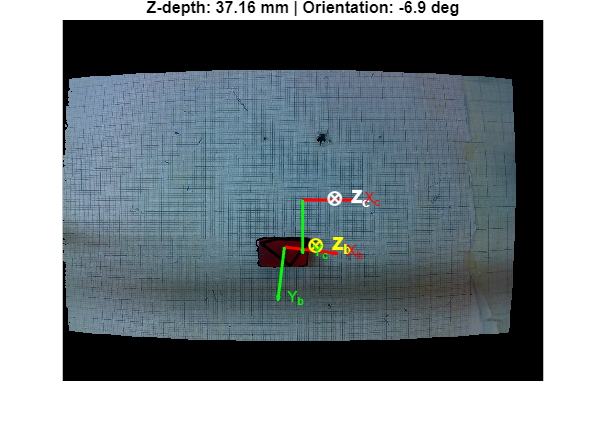

% Drawing frames
figure('Name', 'Pose Estimation Output');
imshow(imgRGB); hold on;
axisLen = 70;

% Block frame
plot(rect_x, rect_y, 'k', 'LineWidth', 2); % Tight Outline
quiver(block_cx, block_cy, axisLen*cos(theta), -axisLen*sin(theta), 0, 'r', 'LineWidth', 2); 
quiver(block_cx, block_cy, axisLen*sin(theta), axisLen*cos(theta), 0, 'g', 'LineWidth', 2);  
text(block_cx, block_cy, '  \otimes Z_b', 'Color', 'y', 'FontSize', 12, 'FontWeight', 'bold');
text(block_cx + axisLen*cos(theta), block_cy - axisLen*sin(theta), ' X_b', 'Color', 'r');
text(block_cx + axisLen*sin(theta), block_cy + axisLen*cos(theta), ' Y_b', 'Color', 'g');

% Camera frame
quiver(cx_img, cy_img, axisLen, 0, 0, 'r', 'LineWidth', 2); 
quiver(cx_img, cy_img, 0, axisLen, 0, 'g', 'LineWidth', 2); 
text(cx_img, cy_img, '  \otimes Z_c', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
text(cx_img + axisLen, cy_img, ' X_c', 'Color', 'r');
text(cx_img, cy_img + axisLen, ' Y_c', 'Color', 'g');

title(sprintf('Z-depth: %.2f mm | Orientation: %.1f deg', Z, rad2deg(theta)));
hold off;